# Sensor Signal Estimation

Imagine you are employed in a wind turbine manufacturing company and have been tasked to design a multisensor signal estimation algorithm for the blade pitching mechanism of the wind turbine. In order to measure the pitch angle ˆω, the blade is equipped with a rotary encoder connected to the blade bearing, where the sensor noise is ν ∼ N(0, 9). 

## Task 1: MMSE estimator 

### Task 1.1: UNIFORM PRIOR KNOWLEDGE

Write a Matlab script to calculate the MMSE estimator, when the prior knowledge of the angle is uniformly distributed in the range 0◦ ≤ ωˆ ≤ 30◦ . Consider the scenarios where: 

- The entire measurement vector encoder.mat is provided. 

- Only the five first elements of the provided measurement vector are available.

#### Solution:

#### Load the data:

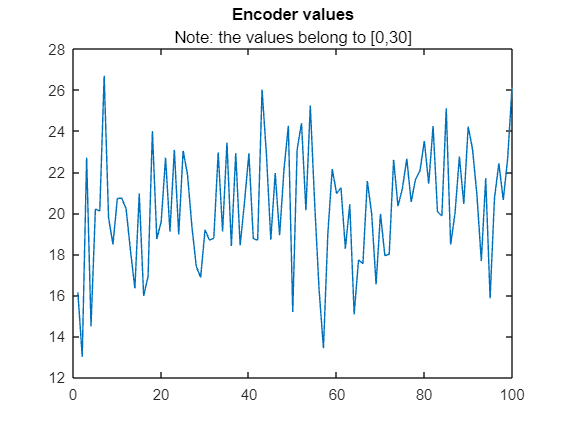

clear
load('encoder.mat')

figure;
plot(encoder);
title("Encoder values");
subtitle("Note: the values belong to [0,30]");

#### Shift the data:

The encoder values are distributed from [0,30].

Since the integral requires symmetric distribution, shift the encoder values by -15 so that it the new distribution is [-15,15]. The result has to be shifted back by adding +15.

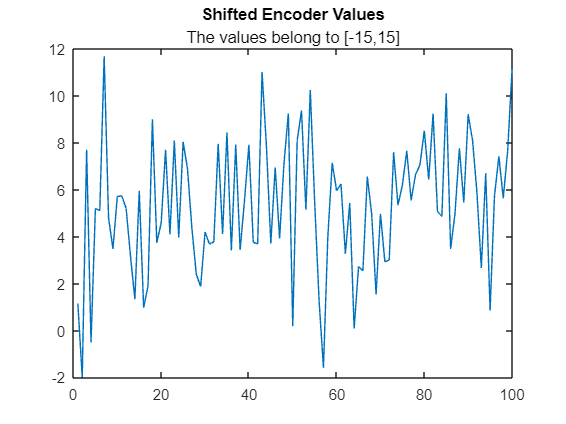

encoder_ = encoder - 15;

figure;
plot(encoder_);
title("Shifted Encoder Values");
subtitle("The values belong to [-15,15]");

With full data:

sigma2 = 9;

% After shifting
w_min = -15;
w_max = 15;

MMSE_full_shifted = MMSE(encoder_, sigma2, w_min, w_max);
MMSE_full = MMSE_full_shifted + 15;

disp("UNIFORM PRIOR KNOWLEDGE:")

UNIFORM PRIOR KNOWLEDGE:


disp("MMSE using the full encoder values: ")

MMSE using the full encoder values: 


disp(MMSE_full)

   20.3131




MMSE_5_shifted = MMSE(encoder_(1:5,:), sigma2, w_min, w_max);
MMSE_5 = MMSE_5_shifted + 15;

disp("MMSE using the first 5 encoder values: ")

MMSE using the first 5 encoder values: 


disp(MMSE_5)

   17.3125



### Task 1.2: GAUSSIAN PRIOR KNOWLEDGE

Extend the script and calculate the MMSE estimator in the case when the prior knowledge is Gaussian distributed with a mean value of 15 and variance of 4. As before, consider both scenarios on the availability of measurements and use the same measurement vector encoder.mat. 

## Task 2: Sequential MMSE estimator 

Extend the script and use the appropriate estimator in the case when the prior knowledge is Gaussian distributed with a mean value of 15 and variance of 4 and the measurements arrive in a sequential manner. As before, consider both scenarios on the availability of measurements and use the same measurement vector encoder.mat.